# Tutorial04 Simulating and Imaging Randomly Diffusing Molecules

#### Notes

Note.

Save all my code. They will be reused and build on each other.

Objective: To be more famiiar with Matrix multiplications through a variation of a random walk.

2. Simulating a Random Walk in 1D

1.. Initialize two matrices

% Parameters
L = 500

L = 500

n_particle = 500

n_particle = 500

n_kicks = 10000

n_kicks = 10000


f = zeros(n_kicks, n_particle);
x = zeros(n_kicks, n_particle);

2.. Assign the initial particle positions in f(1, :) such that the n_p particles are uniformly disributed across the Universe.

% Initially did
% f(1,:) = length*rand(1, n_particle)

% After reaching step 5, for convenience, decided to refer to the solution.
f(1,:) = randperm(L)

f =     78   292    18   166   154   101   176   471   315   466    90   284   277   438   145   488   291   476   434    66   143   203   396   386   279   454   115   140   428   452   132   416   383    63   355   295    76   182   150   379   492   333    82   445    26   302    60   103   465   168
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

3.. Store displacement of each kick.

Received help from solution doc.

% Assign kicks at each time step.
f(2:end,:) = randn(n_kicks-1, n_particle)

f =    78.0000  292.0000   18.0000  166.0000  154.0000  101.0000  176.0000  471.0000  315.0000  466.0000   90.0000  284.0000  277.0000  438.0000  145.0000  488.0000  291.0000  476.0000  434.0000   66.0000  143.0000  203.0000  396.0000  386.0000  279.0000  454.0000  115.0000  140.0000  428.0000  452.0000  132.0000  416.0000  383.0000   63.0000  355.0000  295.0000   76.0000  182.0000  150.0000  379.0000  492.0000  333.0000   82.0000  445.0000   26.0000  302.0000   60.0000  103.0000  465.0000  168.0000
    0.7166   -0.0543   -0.2181   -0.9821   -1.0409    0.9013    0.8026   -0.2206    0.5728    0.2593    0.4696   -1.2683   -1.7311    0.6824   -0.7001    1.1497    1.6913   -0.1439    0.0007   -0.4276   -0.1613    1.3110   -1.8250   -2.4318   -0.1346    0.1372    1.3551   -0.7654    0.4468   -0.3570    0.3367    1.2991   -0.3985   -1.4469   -1.1541    0.9663   -0.0144   -1.7701    0.3242    0.6528    0.8997   -1.3378    0.8040   -0.6612   -1.0990   -0.3679   -1.2739    1.4577   -0.8403   -0

Note. Difference between **rand** and **randn**.

**rand**: uniformly distributed random numbers. Returns random #s between 0 and 1 from uniform distribution.

**randn**: normally(Gaussian) distributed random numbers. Returns random #s of mean 0 and variance 1.

4.. Assign x to the particle trajectories. Use **cumsum** and mod.

% help cumsum
% stepx = cumsum(-1+2*stepx)
x = cumsum(f)

x =    78.0000  292.0000   18.0000  166.0000  154.0000  101.0000  176.0000  471.0000  315.0000  466.0000   90.0000  284.0000  277.0000  438.0000  145.0000  488.0000  291.0000  476.0000  434.0000   66.0000  143.0000  203.0000  396.0000  386.0000  279.0000  454.0000  115.0000  140.0000  428.0000  452.0000  132.0000  416.0000  383.0000   63.0000  355.0000  295.0000   76.0000  182.0000  150.0000  379.0000  492.0000  333.0000   82.0000  445.0000   26.0000  302.0000   60.0000  103.0000  465.0000  168.0000
   78.7166  291.9457   17.7819  165.0179  152.9591  101.9013  176.8026  470.7794  315.5728  466.2593   90.4696  282.7317  275.2689  438.6824  144.2999  489.1497  292.6913  475.8561  434.0007   65.5724  142.8387  204.3110  394.1750  383.5682  278.8654  454.1372  116.3551  139.2346  428.4468  451.6430  132.3367  417.2991  382.6015   61.5531  353.8459  295.9663   75.9856  180.2299  150.3242  379.6528  492.8997  331.6622   82.8040  444.3388   24.9010  301.6321   58.7261  104.4577  464.1597  167

x = mod(x, 500)

x =    78.0000  292.0000   18.0000  166.0000  154.0000  101.0000  176.0000  471.0000  315.0000  466.0000   90.0000  284.0000  277.0000  438.0000  145.0000  488.0000  291.0000  476.0000  434.0000   66.0000  143.0000  203.0000  396.0000  386.0000  279.0000  454.0000  115.0000  140.0000  428.0000  452.0000  132.0000  416.0000  383.0000   63.0000  355.0000  295.0000   76.0000  182.0000  150.0000  379.0000  492.0000  333.0000   82.0000  445.0000   26.0000  302.0000   60.0000  103.0000  465.0000  168.0000
   78.7166  291.9457   17.7819  165.0179  152.9591  101.9013  176.8026  470.7794  315.5728  466.2593   90.4696  282.7317  275.2689  438.6824  144.2999  489.1497  292.6913  475.8561  434.0007   65.5724  142.8387  204.3110  394.1750  383.5682  278.8654  454.1372  116.3551  139.2346  428.4468  451.6430  132.3367  417.2991  382.6015   61.5531  353.8459  295.9663   75.9856  180.2299  150.3242  379.6528  492.8997  331.6622   82.8040  444.3388   24.9010  301.6321   58.7261  104.4577  464.1597  167

**cumsum**: cumulative sum of elements. Check documentation how it works for a matrix.

Sample Code

`Cumsum of each column`

`A = [1 4 7; 2 5 8; 3 6 9]`

`A = `*3×3*

`     1     4     7`

`     2     5     8`

`     3     6     9`

`B = cumsum(A)`

`B = ``3×3`

`     1     4     7`

`     3     9    15`

`     6    15    24`

`Cumsum of each row`

`A = [1 3 5; 2 4 6]`

`A = ``2×3`

`     1     3     5`

`     2     4     6`

`B = cumsum(A,2)`

`B = ``2×3`

`     1     4     9`

`     2     6    12`

**mod**: Takes mod. 

Sample code.

q = [0:10] 

mod(q,5)

mod(q,4)

Q = [0:10;0:10;0:10] 

mod(Q,5) 

mod(Q,2)

Here, mod is used to ensure the particles stay in the universe.

5.. Visualizing particle trajectories by creating an *image*.

I(x,t). corresponds to the # of particles at location x at time t. 

Image: a matrix that represents the grid of pixels, whose entires contain some info about those pixels - here, it's intensity. c.f. The higher the count of a pixel, the brighter it'll be.

% first, use ceiling to discretize x.
x = ceil(x)

x =     78   292    18   166   154   101   176   471   315   466    90   284   277   438   145   488   291   476   434    66   143   203   396   386   279   454   115   140   428   452   132   416   383    63   355   295    76   182   150   379   492   333    82   445    26   302    60   103   465   168
    79   292    18   166   153   102   177   471   316   467    91   283   276   439   145   490   293   476   435    66   143   205   395   384   279   455   117   140   429   452   133   418   383    62   354   296    76   181   151   380   493   332    83   445    25   302    59   105   465   168
    79   292    18   164   155   104   178   472   318   468    91   283   276   439   144   491   292   477   434    68   144   204   395   384   279   456   116   139   429   453   131   416   385    62   356   298    78   180   150   380   492   333    84   444    23   300    57   105   464   168
    81   294    20   164   157   105   178   472   316   468    90   283   275   438   145   


% create image to store result.
% initialize image
I = zeros(L, n_kicks)

I =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


% for each number from 1 to 500, count the occurence and store in the matrix.
for n = 1:n_kicks
    % disp(n)
    location_ranges = 1:500;
    [counts, ind] = histc(x(n, :), location_ranges);
    % transpose(counts)
    I(:, n) = transpose(counts);  % can use " counts.' "
end

I

I =      1     0     1     0     2     0     1     1     1     0     0     0     1     1     0     0     1     0     0     0     1     1     0     1     0     0     0     0     1     1     1     0     1     0     0     0     1     0     1     1     1     1     1     0     1     1     1     0     0     0
     1     2     0     2     0     2     0     0     0     1     1     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     0     1     2     2     1     1     0     0     0     0     0     1     0     1     1     1     1     1
     1     1     2     0     1     3     2     2     2     1     0     2     3     3     0     1     1     1     0     1     1     0     0     0     1     1     0     0     1     0     0     1     2     2     1     1     1     1     0     0     2     0     0     0     0     2     3     2     2     0
     1     1     1     1     2     0     2     2     2     3     2     1     0     0     1   

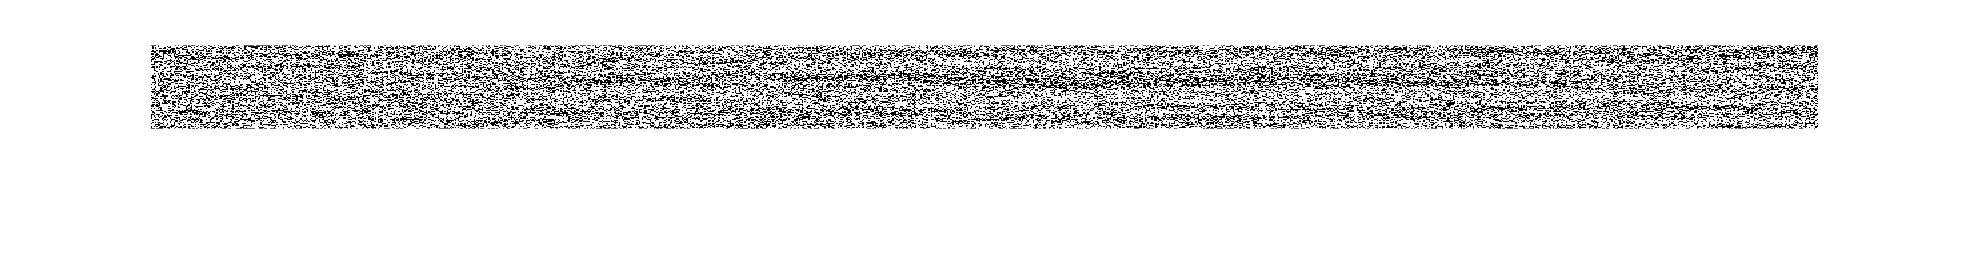

%groupcounts(x)

imshow(I)

Original image

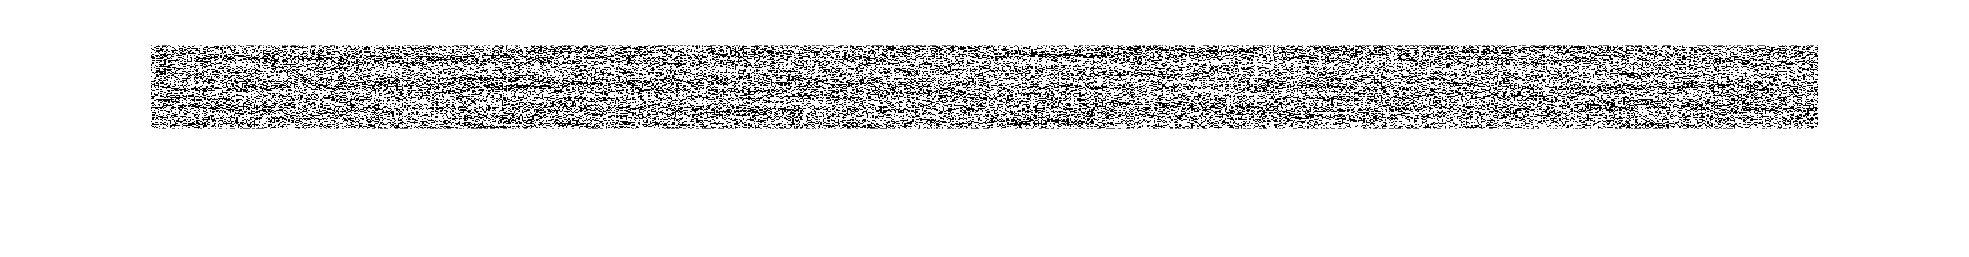

Choosing subsection of the matrix and showing it.

I_section = I(:, 3:950)

I_section =      1     0     2     0     1     1     1     0     0     0     1     1     0     0     1     0     0     0     1     1     0     1     0     0     0     0     1     1     1     0     1     0     0     0     1     0     1     1     1     1     1     0     1     1     1     0     0     0     0     1
     0     2     0     2     0     0     0     1     1     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     0     1     2     2     1     1     0     0     0     0     0     1     0     1     1     1     1     1     1     0
     2     0     1     3     2     2     2     1     0     2     3     3     0     1     1     1     0     1     1     0     0     0     1     1     0     0     1     0     0     1     2     2     1     1     1     1     0     0     2     0     0     0     0     2     3     2     2     0     0     1
     1     1     2     0     2     2     2     3     2     1     0     0     1     0 

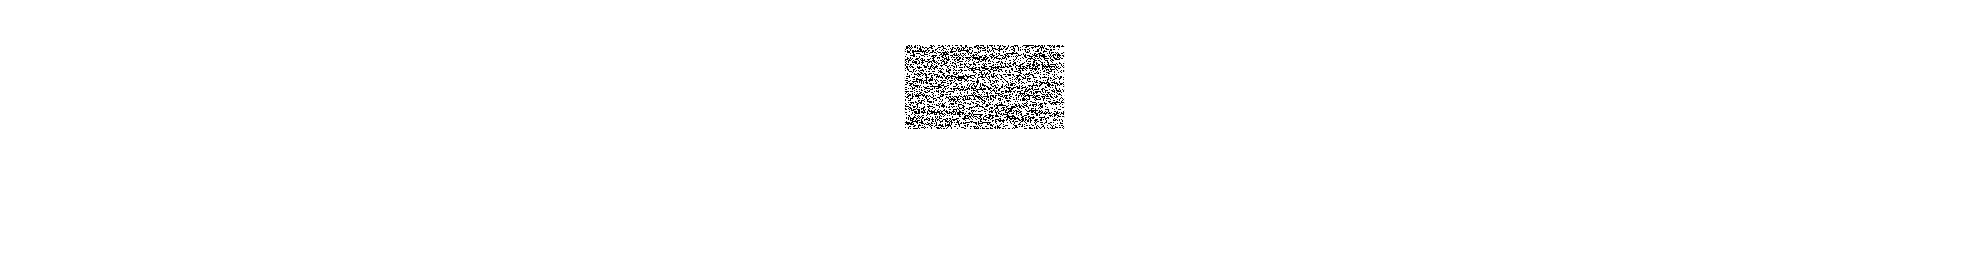

imshow(I_section)

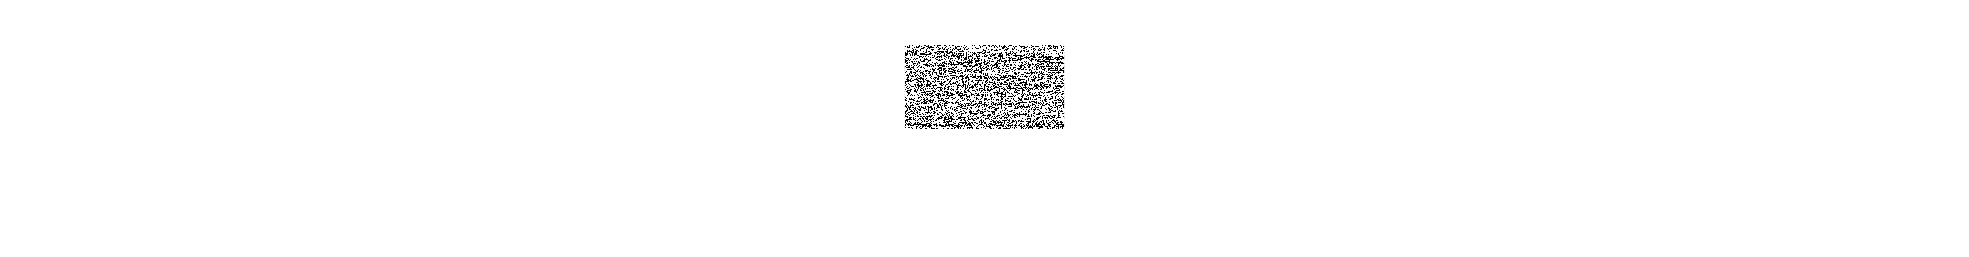

6.. Calculate the variance in positions sampled by each particle.

var_particles = var(transpose(I))

var_particles =     1.0059    1.0703    1.0066    1.0398    1.0108    1.0462    1.0322    1.0290    1.0413    1.0186    0.9532    0.9594    0.9763    0.9603    0.9361    1.0005    0.9826    0.9975    0.9607    0.9819    0.9821    0.9811    1.0000    0.9348    0.9649    0.9788    0.9549    0.9442    0.8941    0.9174    0.8952    0.9017    0.8800    0.9067    0.9163    0.8781    0.8309    0.8580    0.8432    0.8443    0.8672    0.8653    0.8469    0.8760    0.8443    0.8640    0.8869    0.8881    0.8855    0.8730



% Avg value for variance over all particles:
[temp, arrL] = size(var_particles)

temp = 1

arrL = 500

avg_variance = mean(sum(var_particles)) / arrL

avg_variance = 0.9884

The average value for variance over all particles, after a couple of runs of the program, was very close to 1: e.g. 0.9861, 0.9894, 0.9938. This IS what we expect, because the values are pretty much 1, and the kicks were Gaussian-distributed, which means it has variance 1.

7. Define the deffusion coefficient as D = var/(2*N_kicks). Calculate D.

D = avg_variance/(2*n_kicks)

D = 4.9422e-05

The output: `D = 4.9521e-05, D = 4.9422e-05`

`When I googled, I found:`

`"`In an aqueous (water) solution, typical diffusion **coefficients** are in the range of 10 -10 to 10 -9 m 2 /s`"`

`and,`

`"`A typical diffusion coefficient for a molecule in the gas phase is in the range of **10 -6 to 10 -5 m 2 /s**.`".`

`If we assume that the universe as in "gas phase", then it seems to be falling in the range 10^-6 to 10^-5.`

`8.. `